### Chapter 2 - Linear Time-Invariant Systems

#### 2.1 Tutorial Convoluation

**(a)** Consider the finite-length signal

        $\;x\left\lbrack n\right\rbrack =\left\lbrace \begin{array}{ll}
1 & 0\le n\le 5\\
0 & \textrm{otherwise}
\end{array}\right.$             (2.5)

Analytically determine $$y[n]=x[n]*x[n]$$

`2.1a Result Analysis`


$$y_1[n] = x[n]*h[n]= \sum\limits_{k= - \infty}^\infty  x[k]*h[n-k]$$



$$y_1[n] = \sum\limits_{k= 0}^{5}  x[k]*x[n-k]$$


$k=0 \Longrightarrow y_1[0]= 1$ ,       $k=1 \Longrightarrow y_1[1]= 2$

$k=2 \Longrightarrow y_1[2]= 3$,        $k=3 \Longrightarrow y_1[3]= 4$

$k=4 \Longrightarrow y_1[4]= 5$,        $k=5 \Longrightarrow y_1[5]= 6$

$k=6 \Longrightarrow y_1[6]=5$,        $k=7 \Longrightarrow y_1[7]= 4$

$k=8 \Longrightarrow y_1[8]= 3$,        $k=9 \Longrightarrow y_1[9]= 2$


$$k=10 \Longrightarrow y_1[10]= 1$$


**(b)** Compute the non-zero samples of $$y[n]=x[n]*x[n]$$ using ***conv****, and store these samples in the vectory y.  *plot the results and check you plot to see if it agrees what you got in (a) and it shold also agrees with Figure 2.1.

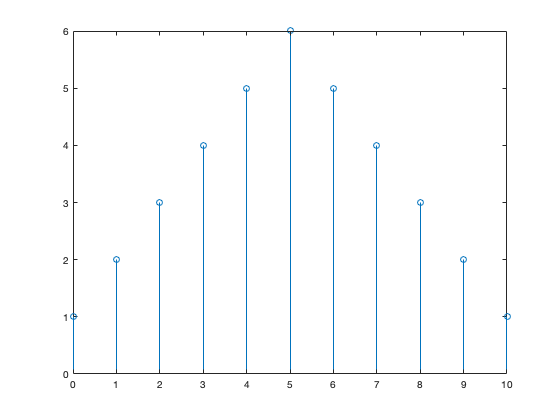

% L2_1b.m

n=[0:5];
xn=n*0;
for i=n
    
    if 0<=i & i<=5
        xn(i+1)=1;
    end
end
yn=conv(xn,xn);
n=[0:length(yn)-1];
stem(n,yn);

**(c)**  Consider the finite-length signal

                $h\left\lbrack n\right\rbrack =\left\lbrace \begin{array}{ll}
n, & 0\le n\le 5\\
0, & \textrm{otherwise}
\end{array}\right.$            (2.6)

Analytically compute $$y[n]=x[n]*h[n]$$. Next, compute ***y*** using ***conv, ***then plot your results., As a check you plot should agree with Figuree 2.2 and your analytical derivation.

Your Analytical Solution:

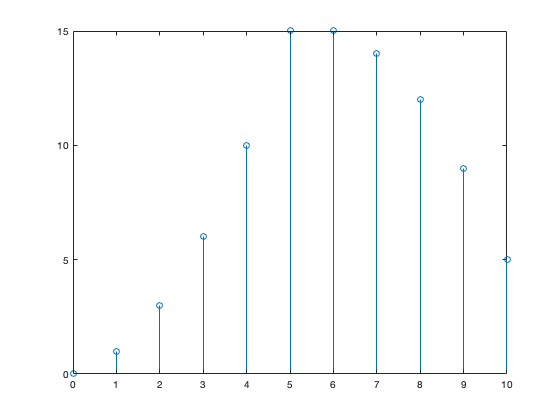

% L2_1c.m
n=[0:5];
xn=n*0;
y=n*0;
for i=n
    
    if 0<=i & i<=5
        y(i+1)=i;
        xn(i+1)=1;
    end
end
yn=conv(xn,y);
n=[0:length(yn)-1];

stem(n,yn);

**(d) ** Let $$y_2[n]=x[n]*h[n+5]$$, compare to the signal y[n] derived in Part-C, what is your conclusion?

**Put your Analysis Here:**

It is the delayed version of y[n] in Part-C and the delay is 5 unit.

**(e)  **Use conv to compute the $$y_2[n]$$, then plot the results which should agree with Figure 2.3.

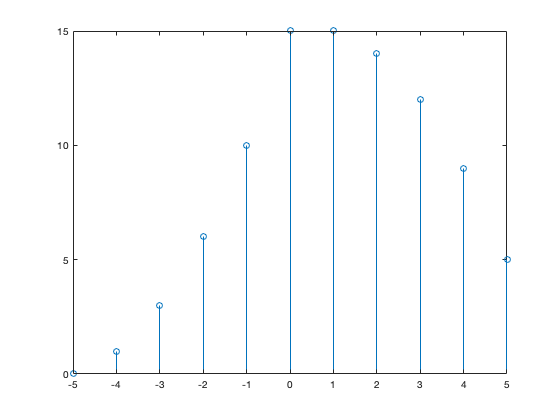

% L2_1e.m
n1=[0:5];
xn=n1*0;
hn5=n1*0;
for i=n
    
    if 0<=i & i<=5
        hn5(i+1)=i;
        xn(i+1)=1;
    end
end
yn=conv(xn,hn5);
n=[-5:5];
stem(n,yn);

#### 2.2 Tutorial Filter

The filter command computes the output of a causal, LTI system for a given input when the system is specifed by a linear constant-coefficient difference equation.  Specifically, consider an LTI system satisfying the difference equation:

                $\sum^k_{k=0}a_ky[n-k]=\sum^M_{m=0}b_mx[n-m]$             (2.7)

where x[n] is the system input and [n] is the system output.  

(a) Define coffeicient vectors a1 and b1 t describe the causal LTI system specified by $$y[n]=0.5x[n]+x[n-1]+2x[n-2]$$.

**Your Answer:  **

(b)  Define coefficient vector a2 and b2 to describe the causal LTI system sepecified by $$y[n]=0.8y[n-1]+2x[n]$$.

**You Answer:**   

( c )  Define coefficient vector a3 and b3 to describe the causal LTI system specifed by $$y[n]-0.8y[n-1]=2x[n-1]$$

**Your Answer:**  

(d)   For each these three systems, use ***filter*** to compute the response ***y[n]*** on the interval $$1\le n \le 4$ $ to the imput signal $$x[n]=nu[n]$$.  You should begin by defining the vector x = [1 2 3 4] which contains x[n] on the interval $$1\le n \le 4$ $.  The result of using fitler for each system is shown below:

% L2_2.m
% MATLAB code for 2.2 Tutorial filter for problem a), b), c) and d) on the Companion book in page 22-24
a1=[1];
b1=[0.5 1 2];
x=[1 2 3 4];
y1=filter(b1,a1,x)

y1 =     0.5000    2.0000    5.5000    9.0000



a2=[1 -0.8];
b2=2;
y2=filter(b2,a2,x)

y2 =     2.0000    5.6000   10.4800   16.3840



a3=[1 -0.8];
b3=[0 2];
y3=filter(b3,a3,x)

y3 =          0    2.0000    5.6000   10.4800


**2.2 (e) and (f):**

The function filter can also be used to perform discrete-time convolution.  To Illustrate how to use filter to implement a discrete-time convolution, consider the convolution of x[n] in Eq. (2.5) and h[n] in Eq. (2.6).

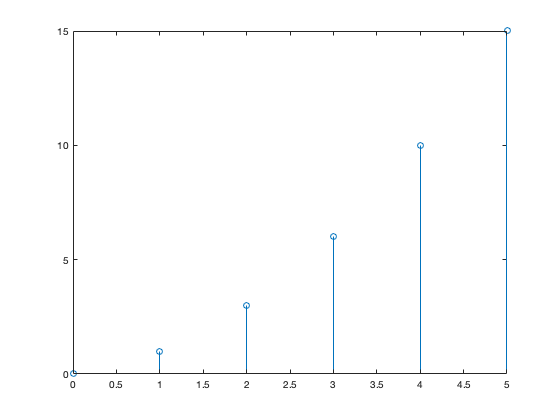

% L2_2e_f.m
% use the filter function to perform convoluation for discrete-time systems.
n1=[0:5];
xn=n1*0;
hn=n1*0;
for i=n
    
    if 0<=i & i<=5
        hn(i+1)=i;
        xn(i+1)=1;
    end
end
yn=filter(hn,1,xn);
stem(n1,yn);

**2.2 (g):**

Define a vector x2 to contain x[n] on a interval $$0\le n\le 10$$, and use $$y2=filter(h,1,x2)$$; to compare the convolution on this interval.  Plot your results and very that it agrees with Figure 2.2.

% L2_2g.m
% use the filter function to perform convoluation for discrete-time systems.
n1=[0:10];
x2=n1*0;
hn=n1*0;
for i=n
    
    if 0<=i & i<=5
        hn(i+1)=i;
        x2(i+1)=1;
    end
end
yn2=filter(hn,1,x2);
stem(n1,yn2);

**2.2 (h) and (i):**

Like *conv, filter* can also be used to implement a LTI system which has a noncausal impulse response.  

**(h)** Consider the impulse response $$h_2[n]=h[n+5]$$, h[n] is defined in Eq. (2.6). Store $$h_2[n]$$ on the interval $$-5\le n\le 0$$ in the vector h2.

**(i) **Excute the command $$y_2=filter(h2,1,x)$$  and create a vector ny2 which contains indices of the samples of $$y_2[n]=h_2[n]*x[n]$$ stored in y2.  Plot your result and check how does this plot compare with Figure2.4?

%L2_2h_i.m
n1=[0:5];
xn=n1*0;
h2=n1*0;
for i=n
    
    if 0<=i & i<=5
        h2(i+1)=i;
        xn(i+1)=1;
    end
end
y2=filter(h2,1,xn);
stem(n1,y2);

**2.2 (j)**  Create a vector x2 such that  ***filter(h2,1,x2)*** returns all the nonzero samples of y2[n].

**Analysis:**

**To get out of one only nonzero value of y2[n], we need to shift y2[n] left by one unit, which is y2[n+1].**

**Based on LTI property, it can be done by shift the imput by one unit. As you can see in the plot below, the**

**system output is shift one unit to left (or advanced by one unit). It contains only the non-zero values.**

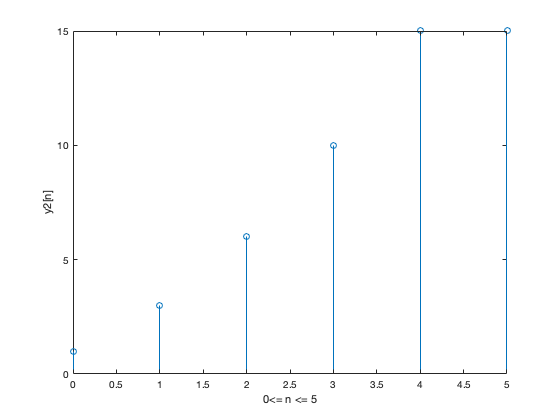

 % L2_2j.m

n1=[0:5];
h2=n1*0;
for i=n
    
    if 0<=i & i<=5
        h2(i+1)=i;
    end
end
n2=[0:6];
xn2=n2*2;
xn2(1:6)=1;
y=filter(h2,1,xn2);

for i=n1
    y2(i+1)=y(i+2);
end
stem(n1,y2);xlabel('0<= n <= 5');ylabel('y2[n]');

2.7 Discrete-Time Convolution

In these problems, you will define some discrete-time signals and the impulse responses of some discrete-time

LTI systems. Then the output of the LTI systems can be computed using **conv**.

(a). Since the MATLAB function **conv** does not keep track of the time indices of the sequences that are

convolved, you will have to do some extra bookkeping in order to determine the proper indices for the result of

the **conv** function. For the sequences $h[n]=2\delta[n+1]-2\delta[n-1], \ and\ x[n]=\delta[n]+\delta[n-2]$construct vectors

h and x. Define $y[n]=x[n]*h[n]$ and compute $y=conv(h,x)$. Determine the proper time indexing for y and

store this set of time indices in the vector ny. Plot y[n] as a function of n using $stem(ny,y)$

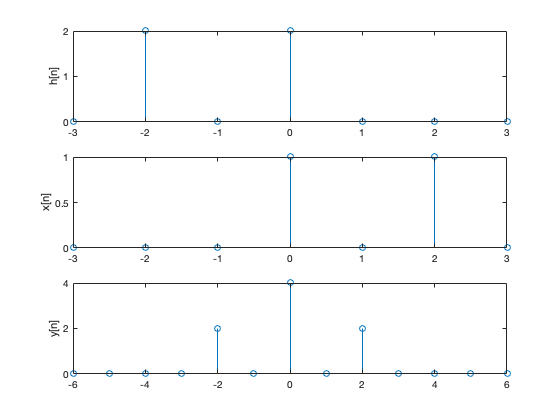

clf;
n1=[-3:3]; 
h=n1*0;
h(2)=2; 
h(3)=0;
h(4)=2;
subplot(3,1,1); stem(n1,h); ylabel('h[n]');
n2=[-3:3]; 
x=n2*0;
x(4)=1; 
x(6)=1;
subplot(3,1,2); stem(n2,x); ylabel('x[n]');
y=conv(h,x);
n3=[-6:6];
subplot(3,1,3); stem(n3,y); ylabel('y[n]');

(b). Consider two finite-length sequences h[n] and x[n] that are represnted in MATLAB using the vectors h and x, with corresponding time indices given by nh=[a:b] and nx=[c:d]. The function call $y=conv(h,x)$ will return in the vector y the proper sequence values of $y[n]=h[n]*x[n];$ however, you must determine a corresponding set of time indices ny. To help you construct ny, consider the sequence $h[n]=\delta[n-a]+\delta[n-b] \ and\ x[n]=\delta[n-c]+\delta[n-d]$. Determine analytically the convolution $y[n]=h[n]*x[n]$. From your answer, determine what ny should be in terms of a, b, c, and d. To check your result, verify that y[n] is of length M+N-1 when a=0, b=N-1, c=0, and d=M-1.

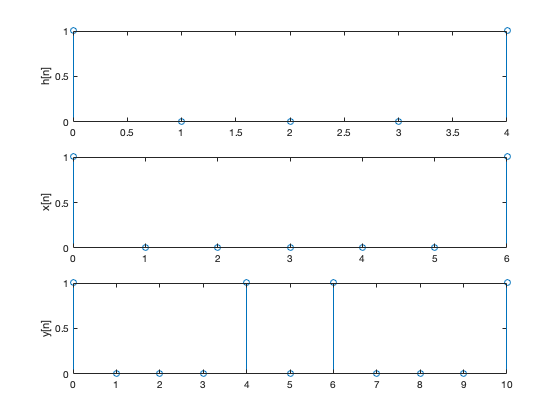

% 2.7b to verify that y[n] is of length M+N-1
% where a=0, b=N-1, c=0 and d=M-1
clf;
N=5; M=7;
n1=[0:N-1];
h=n1*0; 
h(1)=1;
h(5)=1;
subplot(3,1,1); stem(n1,h); ylabel('h[n]');
n2=[0:6];
x=n2*0; 
x(1)=1; 
x(7)=1;
subplot(3,1,2); stem(n2,x); ylabel('x[n]');
y=conv(h,x);
n3=[0:10];
subplot(3,1,3); stem(n3, y); ylabel('y[n]');

2.7b Results Analysis

The plots above verifies that y[n] is of length M+N-1 when a=0, b=N-1, c=0, and d=M-1.

In this case the length of $y[n]=M+N-1=11$

(c ). Consider an input x[n] and unit impulse response h[n] given by:

$x[n]=(1/2)^{n-2}u[n-2]$,


$$h[n]=u[n+2]$$


if you wish to compute $y[n]=h[n]*x[n]$ using **conv**, you must deal appropriately with the infinte length of both x[n] and h[n]. Store in the vector x the values of x[n] for $0\le n\le 24$ and store in the vector h the values of h[n] for $-2\le n\le 14$ . Now store in the vector y the result of the function call $conv(h,x)$. Since you have truncated

both h[n] and x[n], argue that only a portion of the output of **conv** will be valid. Specify which values in the output are valid and which are not. Determine the values of the parameters a, b, c, and d such that nx=[a:b] and nh=[c:d], and use your answer from Part (b) to construct the proper time indices for y. Plot y[n] using **stem**,

and indicate which values of y[n] are correct, and which values are invalid. Be sure to properly label the time axis for y[n].

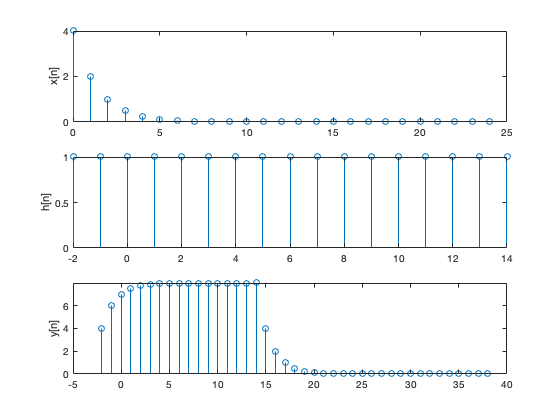

% 2.7c
clf;
n1 =[0:24];
x=n1*0;
for i=n1
x(i+1)=(1/2)^(i-2);
end
subplot(3,1,1); stem(n1,x); ylabel('x[n]');
n2=[-2:14]; 
h=n2*0;
h(1:end)=1;
subplot(3,1,2); stem(n2,h); ylabel('h[n]');
y=conv(x,h);
n3=[-2:38];
subplot(3,1,3); stem(n3,y); ylabel('y[n]');

2.7c Results Analysis

Given index for the vector x the values of x[n] for $0\le n\le 24$ (N=25) and index for the vector h the values of

h[n] for $-2\le n\le 14$ (M=17), we have the values of the parameters a=0, b=24, c=-2, and d=14. Using the result

for Part(b), the size of y[n] should be N+M-1=41, the indix for y[n] should be ny=[-2, 38]. y[n] has correct values

in the range of [-2, 38] and the values outside that range are invalid.